L = [180 100 0];
v_optimal = fminsearch(@(v)  abstand_zum_loch(v, L), [10 40 10])

v_optimal =    28.5610   15.8672   45.8809


v_optimal_2 = fminsearch(@(v)  abstand_zum_loch(v, L), [10 40 50])

v_optimal_2 =    26.7740   14.8745   50.7204


norm(v_optimal)

ans = 56.3255

v_xy = v_optimal;
v_xy(3)=0; % Projektion der Geschwindigkeit auf die xy-Ebene
alpha = atan2d(v_xy(2), v_xy(1)) % Winkel zwischen v_xy und der x-Achse

alpha = 29.0546

cos_beta = dot(v_optimal, v_xy) / (norm(v_optimal) * norm(v_xy));
beta = acosd(cos_beta)

beta = 54.5446

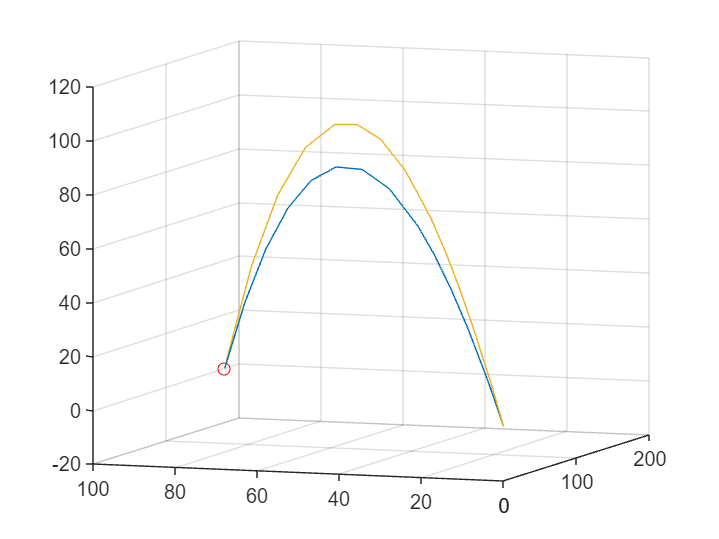

% Variante:
% beta = asind(v_optimal(3)/norm(v_optimal))
options = odeset('Events', @boden);
[t,u]=ode45(@golf, [0 60], [0 0 0 v_optimal], options);

hold off
plot3(u(:,1), u(:,2), u(:,3))
hold on
plot3(L(1), L(2), L(3), 'ro')
[t,u]=ode45(@golf, [0 60], [0 0 0 v_optimal_2], options);
plot3(u(:,1), u(:,2), u(:,3))
grid on